# **Apomorphine Test Analysis - Cylindrical Arena**

**For studying stereotypical behaviors induced by apomorphine**

**Arena: 20 cm diameter x 40 cm height**

**Test duration: 30 minutes**

#### **A.Babaei**

clear; clc; close all;

%% ===== USER PARAMETERS =====
arena_diameter_cm = 20;      % Arena diameter in cm
arena_height_cm = 40;        % Arena height in cm
test_duration_min = 30;      % Test duration in minutes
peripheral_width_cm = 5;     % Width of peripheral zone (cm)
central_zone_diameter_cm = 10; % Central zone diameter (cm)

% Apomorphine-specific parameters
apomorphine_dose = 0.5;      % Dose in mg/kg (adjust based on your experiment)
injection_time_min = 5;      % Time of injection (minutes after start)
baseline_duration_min = 5;   % Baseline period before injection

% Movement thresholds (cm/s)
locomotion_threshold = 2.0;  % For general movement
stereotypy_threshold = 5.0;  % For repetitive movements
freezing_threshold = 0.5;    % For freezing behavior

%% ===== DATA LOADING =====
fprintf('=== Apomorphine Test Analysis ===\n');

=== Apomorphine Test Analysis ===


fprintf('Arena: %.0f cm diameter x %.0f cm height\n', arena_diameter_cm, arena_height_cm);

Arena: 20 cm diameter x 40 cm height


fprintf('Test duration: %.0f minutes\n', test_duration_min);

Test duration: 30 minutes


fprintf('Apomorphine dose: %.2f mg/kg\n', apomorphine_dose);

Apomorphine dose: 0.50 mg/kg



% Check for tracking data
if ~exist('track', 'var')
    if exist('Out_Post.mat', 'file')
        load('Out_Post.mat');
        fprintf('Loaded Out_Post.mat\n');
    elseif exist('tracking_data.mat', 'file')
        load('tracking_data.mat');
        fprintf('Loaded tracking_data.mat\n');
    else
        % Try to select file interactively
        [filename, pathname] = uigetfile({'*.mat;*.csv', 'Tracking files'}, ...
                                         'Select tracking data file');
        if isequal(filename, 0)
            error('No tracking data selected.');
        end
        load(fullfile(pathname, filename));
        fprintf('Loaded %s\n', filename);
    end
end

Loaded Out_APO_PD1.mat



%% ===== DATA VALIDATION =====
% Check if we have the necessary data
if ~exist('track', 'var')
    error('No ''track'' variable found in the loaded data.');
end

if ~isstruct(track)
    error('''track'' is not a struct (class: %s).', class(track));
end

fprintf('Available fields in track: %s\n', strjoin(fieldnames(track), ', '));

Available fields in track: Centroid, Head, Tail, Area, Axes, Tracked, Time, Eccentricity, EulerNumber, ConvexHull



%% ===== FRAME RATE & TIME BASE =====
if isfield(track, 'FrameRate')
    fps = track.FrameRate;
    fprintf('Using track.FrameRate: %.2f fps\n', fps);
elseif isfield(track, 'Time') && ~isempty(track.Time)
    Time = track.Time(:);
    fps = 1 / mean(diff(Time));
    fprintf('Calculated from track.Time: %.2f fps\n', fps);
else
    fps = 30; % Default assumption
    fprintf('Using default frame rate: %.0f fps\n', fps);
end

Calculated from track.Time: 29.97 fps



dt = 1/fps;  % Time per frame in seconds
total_frames_expected = test_duration_min * 60 * fps;
fprintf('Expected frames for %.0f min test: %d\n', test_duration_min, total_frames_expected);

Expected frames for 30 min test: 5.394605e+04



%% ===== POSITION DATA EXTRACTION =====
% Find centroid/position data
C = [];
if isfield(track, 'Centroid')
    C = double(track.Centroid);
    fprintf('Using Centroid data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Head')
    C = double(track.Head);
    fprintf('Using Head data (%dx%d)\n', size(C,1), size(C,2));
elseif isfield(track, 'Body_Centroid')
    C = double(track.Body_Centroid);
    fprintf('Using Body_Centroid data (%dx%d)\n', size(C,1), size(C,2));
else
    error('No position data found in track structure.');
end

Using Centroid data (2x53942)



% Handle different coordinate formats
if size(C, 2) == 2 && size(C, 1) > 2
    x = C(:,1);
    y = C(:,2);
elseif size(C, 1) == 2 && size(C, 2) > 2
    x = C(1,:)';
    y = C(2,:)';
else
    error('Unknown coordinate format: %dx%d', size(C,1), size(C,2));
end

% Truncate to expected duration if needed
nFrames = min(total_frames_expected, length(x));
x = x(1:nFrames);
y = y(1:nFrames);
actual_duration_min = nFrames / fps / 60;
fprintf('Actual frames analyzed: %d (%.1f minutes)\n', nFrames, actual_duration_min);

Actual frames analyzed: 53942 (30.0 minutes)



%% ===== CALIBRATION =====
% Calculate arena bounds
min_x = min(x);
max_x = max(x);
min_y = min(y);
max_y = max(y);

arena_width_px = max_x - min_x;
arena_height_px = max_y - min_y;

% Add 5% margins for safety
margin_x = arena_width_px * 0.05;
margin_y = arena_height_px * 0.05;

min_x_arena = min_x - margin_x;
max_x_arena = max_x + margin_x;
min_y_arena = min_y - margin_y;
max_y_arena = max_y + margin_y;

arena_width_px = max_x_arena - min_x_arena;
arena_height_px = max_y_arena - min_y_arena;

% Pixel to cm conversion (using diameter)
px_to_cm = arena_diameter_cm / max(arena_width_px, arena_height_px);
fprintf('Pixel to cm conversion: 1 px = %.4f cm\n', px_to_cm);

Pixel to cm conversion: 1 px = 0.0322 cm



% Arena center in pixels
center_x = (min_x_arena + max_x_arena) / 2;
center_y = (min_y_arena + max_y_arena) / 2;
arena_radius_px = (max(arena_width_px, arena_height_px) / 2);

%% ===== ZONE DEFINITIONS =====
% Convert zone dimensions to pixels
peripheral_width_px = peripheral_width_cm / px_to_cm;
central_radius_px = (central_zone_diameter_cm / 2) / px_to_cm;

% Calculate distance from center for each point
dist_from_center = sqrt((x - center_x).^2 + (y - center_y).^2);

% Zone masks
central_mask = dist_from_center <= central_radius_px;
peripheral_mask = dist_from_center >= (arena_radius_px - peripheral_width_px);
middle_mask = ~central_mask & ~peripheral_mask;

% Calculate zone occupancy
t_seconds = (0:nFrames-1)' * dt;
t_minutes = t_seconds / 60;

time_in_central = sum(central_mask) * dt;
time_in_peripheral = sum(peripheral_mask) * dt;
time_in_middle = sum(middle_mask) * dt;

percent_central = 100 * time_in_central / (nFrames * dt);
percent_peripheral = 100 * time_in_peripheral / (nFrames * dt);
percent_middle = 100 * time_in_middle / (nFrames * dt);

fprintf('\n--- Zone Occupancy ---\n');


--- Zone Occupancy ---


fprintf('Central zone (%.1f cm diameter): %.1f%% of time\n', central_zone_diameter_cm, percent_central);

Central zone (10.0 cm diameter): 14.7% of time


fprintf('Peripheral zone (%d cm width): %.1f%% of time\n', peripheral_width_cm, percent_peripheral);

Peripheral zone (5 cm width): 85.3% of time


fprintf('Middle zone: %.1f%% of time\n', percent_middle);

Middle zone: 0.0% of time



%% ===== SPEED & LOCOMOTION ANALYSIS =====
% Calculate speed
if nFrames > 1
    dx = diff(x);
    dy = diff(y);
    distance_px_frame = sqrt(dx.^2 + dy.^2);
    distance_cm_frame = [0; distance_px_frame] * px_to_cm;
else
    distance_cm_frame = zeros(nFrames, 1);
end

speed_cm_s = distance_cm_frame / dt;

% Smooth speed for analysis (5-frame moving average)
if nFrames >= 5
    kernel = ones(5,1)/5;
    speed_smoothed = conv(speed_cm_s, kernel, 'same');
    speed_smoothed(1:2) = speed_cm_s(1:2);
    speed_smoothed(end-1:end) = speed_cm_s(end-1:end);
else
    speed_smoothed = speed_cm_s;
end

total_distance_cm = sum(distance_cm_frame);

% Movement classification
moving = speed_smoothed > locomotion_threshold;
slow_moving = (speed_smoothed > freezing_threshold) & (speed_smoothed <= locomotion_threshold);
freezing = speed_smoothed <= freezing_threshold;
stereotypy = speed_smoothed > stereotypy_threshold;

time_moving = sum(moving) * dt;
time_slow = sum(slow_moving) * dt;
time_freezing = sum(freezing) * dt;
time_stereotypy = sum(stereotypy) * dt;

percent_moving = 100 * time_moving / (nFrames * dt);
percent_slow = 100 * time_slow / (nFrames * dt);
percent_freezing = 100 * time_freezing / (nFrames * dt);
percent_stereotypy = 100 * time_stereotypy / (nFrames * dt);

mean_speed = mean(speed_smoothed, 'omitnan');
max_speed = max(speed_smoothed);

fprintf('\n--- Locomotion Analysis ---\n');


--- Locomotion Analysis ---


fprintf('Total distance: %.1f cm\n', total_distance_cm);

Total distance: 16176.4 cm


fprintf('Mean speed: %.2f cm/s | Max speed: %.2f cm/s\n', mean_speed, max_speed);

Mean speed: 8.99 cm/s | Max speed: 317.28 cm/s


fprintf('Moving (>%.1f cm/s): %.1f%% of time\n', locomotion_threshold, percent_moving);

Moving (>2.0 cm/s): 73.0% of time


fprintf('Slow (%.1f-%.1f cm/s): %.1f%% of time\n', freezing_threshold, locomotion_threshold, percent_slow);

Slow (0.5-2.0 cm/s): 22.1% of time


fprintf('Freezing (<%.1f cm/s): %.1f%% of time\n', freezing_threshold, percent_freezing);

Freezing (<0.5 cm/s): 4.8% of time


fprintf('Stereotypy (>%.1f cm/s): %.1f%% of time\n', stereotypy_threshold, percent_stereotypy);

Stereotypy (>5.0 cm/s): 41.6% of time



%% ===== TIME-BINNED ANALYSIS (Pre/Post Injection) =====
injection_frame = round(injection_time_min * 60 * fps);
baseline_frames = round(baseline_duration_min * 60 * fps);

% Define time periods
pre_injection_mask = (1:nFrames)' <= injection_frame;
post_injection_mask = (1:nFrames)' > injection_frame;
baseline_mask = (1:nFrames)' <= baseline_frames;

% Analyze each period
periods = {'Baseline', 'Pre-Injection', 'Post-Injection'};
masks = {baseline_mask, pre_injection_mask, post_injection_mask};
start_times = [0, 0, injection_time_min];
end_times = [baseline_duration_min, injection_time_min, actual_duration_min];

fprintf('\n--- Time-Binned Analysis ---\n');


--- Time-Binned Analysis ---


fprintf('Injection at %.1f minutes (frame %d)\n', injection_time_min, injection_frame);

Injection at 5.0 minutes (frame 8991)



for i = 1:3
    if i == 1 && baseline_duration_min == 0
        continue; % Skip baseline if duration is 0
    end
    
    mask = masks{i};
    if sum(mask) == 0
        continue;
    end
    
    % Calculate metrics for this period
    period_speed = speed_smoothed(mask);
    period_moving = moving(mask);
    period_central = central_mask(mask);
    period_distance = distance_cm_frame(mask);
    
    period_mean_speed = mean(period_speed, 'omitnan');
    period_percent_moving = 100 * sum(period_moving) / sum(mask);
    period_percent_central = 100 * sum(period_central) / sum(mask);
    period_distance_total = sum(period_distance);
    
    fprintf('\n%s (%.1f-%.1f min):\n', periods{i}, start_times(i), end_times(i));
    fprintf('  Mean speed: %.2f cm/s\n', period_mean_speed);
    fprintf('  %% moving: %.1f%%\n', period_percent_moving);
    fprintf('  %% in center: %.1f%%\n', period_percent_central);
    fprintf('  Distance: %.1f cm\n', period_distance_total);
end


Baseline (0.0-5.0 min):


  Mean speed: 9.34 cm/s


  % moving: 63.2%


  % in center: 17.6%


  Distance: 2802.9 cm



Pre-Injection (0.0-5.0 min):


  Mean speed: 9.34 cm/s


  % moving: 63.2%


  % in center: 17.6%


  Distance: 2802.9 cm



Post-Injection (5.0-30.0 min):


  Mean speed: 8.92 cm/s


  % moving: 75.0%


  % in center: 14.1%


  Distance: 13373.4 cm



%% ===== ROTATIONAL BEHAVIOR ANALYSIS =====
% Apomorphine often induces rotational behavior
if nFrames > 10
    % Calculate angular displacement
    angles = atan2(y - center_y, x - center_x);
    angular_velocity = diff(angles);
    
    % Unwrap angular differences
    angular_velocity(angular_velocity > pi) = angular_velocity(angular_velocity > pi) - 2*pi;
    angular_velocity(angular_velocity < -pi) = angular_velocity(angular_velocity < -pi) + 2*pi;
    
    angular_velocity_deg_s = rad2deg([0; angular_velocity]) / dt;
    
    % Count rotations (full 360° turns)
    cumulative_angle = cumsum(abs(angular_velocity));
    full_rotations = cumulative_angle(end) / (2*pi);
    
    % Direction preference
    clockwise_turns = sum(angular_velocity < 0);
    counterclockwise_turns = sum(angular_velocity > 0);
    rotation_bias = (clockwise_turns - counterclockwise_turns) / length(angular_velocity);
    
    fprintf('\n--- Rotational Analysis ---\n');
    fprintf('Total rotations: %.1f (%.1f rotations/min)\n', full_rotations, full_rotations/actual_duration_min);
    fprintf('Rotation bias: %.3f (negative = clockwise preference)\n', rotation_bias);
    fprintf('Mean angular velocity: %.1f deg/s\n', mean(abs(angular_velocity_deg_s), 'omitnan'));
end


--- Rotational Analysis ---


Total rotations: 363.0 (12.1 rotations/min)


Rotation bias: 0.226 (negative = clockwise preference)


Mean angular velocity: 72.6 deg/s


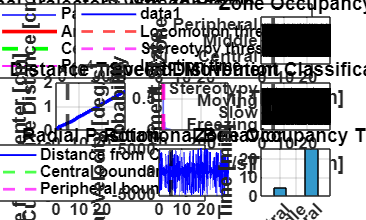


=== Analysis Complete ===


Results saved with prefix: Apomorphine_Analysis_Dose0.50_2025-12-12_00-21-42


Summary saved to: Apomorphine_Analysis_Dose0.50_2025-12-12_00-21-42_summary.csv


Detailed data saved to: Apomorphine_Analysis_Dose0.50_2025-12-12_00-21-42_detailed_data.csv



%% ===== PLOTTING =====
% Set up figure
set(0, 'DefaultAxesFontSize', 12, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontSize', 12, 'DefaultTextFontWeight', 'bold');

% Figure 1: Overview
fig1 = figure('Name', 'Apomorphine Test Overview', 'NumberTitle', 'off', ...
              'Position', [50 50 1400 900]);

% 1. Trajectory with zones
subplot(3,3,1);
plot(x, y, 'b-', 'LineWidth', 0.5);
hold on;
% Draw arena circle
theta = linspace(0, 2*pi, 100);
arena_circle_x = center_x + arena_radius_px * cos(theta);
arena_circle_y = center_y + arena_radius_px * sin(theta);
plot(arena_circle_x, arena_circle_y, 'r-', 'LineWidth', 2);

% Draw central zone
central_circle_x = center_x + central_radius_px * cos(theta);
central_circle_y = center_y + central_radius_px * sin(theta);
plot(central_circle_x, central_circle_y, 'g--', 'LineWidth', 2);

% Draw peripheral zone
peripheral_inner_radius = arena_radius_px - peripheral_width_px;
peripheral_circle_x = center_x + peripheral_inner_radius * cos(theta);
peripheral_circle_y = center_y + peripheral_inner_radius * sin(theta);
plot(peripheral_circle_x, peripheral_circle_y, 'm--', 'LineWidth', 1);

xlabel('X [px]'); ylabel('Y [px]');
title('Animal Trajectory with Zones');
legend('Path', 'Arena', 'Central', 'Peripheral inner', 'Location', 'best');
axis equal; grid on;

% 2. Speed over time
subplot(3,3,2);
plot(t_minutes, speed_smoothed, 'b-', 'LineWidth', 1);
hold on;
yline(locomotion_threshold, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Locomotion threshold');
yline(stereotypy_threshold, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Stereotypy threshold');
xline(injection_time_min, 'k--', 'LineWidth', 2, 'DisplayName', 'Injection time');
xlabel('Time [min]'); ylabel('Speed [cm/s]');
title('Speed Profile');
legend('show', 'Location', 'best');
grid on;
ylim([0 max(20, max_speed*1.1)]);

% 3. Zone occupancy over time
subplot(3,3,3);
zone_plot = zeros(size(t_minutes));
zone_plot(central_mask) = 1;
zone_plot(middle_mask) = 2;
zone_plot(peripheral_mask) = 3;
plot(t_minutes, zone_plot, 'k-', 'LineWidth', 1);
xline(injection_time_min, 'k--', 'LineWidth', 2);
xlabel('Time [min]'); ylabel('Zone');
title('Zone Occupancy');
yticks([1 2 3]);
yticklabels({'Central', 'Middle', 'Peripheral'});
ylim([0.5 3.5]);
grid on;

% 4. Cumulative distance
subplot(3,3,4);
cumulative_distance = cumsum(distance_cm_frame);
plot(t_minutes, cumulative_distance, 'b-', 'LineWidth', 2);
xline(injection_time_min, 'k--', 'LineWidth', 2);
xlabel('Time [min]'); ylabel('Cumulative Distance [cm]');
title('Distance Traveled');
grid on;

% 5. Speed histogram
subplot(3,3,5);
histogram(speed_smoothed, 40, 'FaceColor', 'blue', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(locomotion_threshold, 'r--', 'LineWidth', 2);
xline(stereotypy_threshold, 'm--', 'LineWidth', 2);
xlabel('Speed [cm/s]'); ylabel('Probability');
title('Speed Distribution');
grid on;

% 6. Movement state over time
subplot(3,3,6);
movement_state = zeros(size(t_minutes));
movement_state(freezing) = 1;
movement_state(slow_moving) = 2;
movement_state(moving) = 3;
movement_state(stereotypy) = 4;
plot(t_minutes, movement_state, 'k-', 'LineWidth', 1);
xline(injection_time_min, 'k--', 'LineWidth', 2);
xlabel('Time [min]'); ylabel('Movement State');
title('Movement Classification');
yticks([1 2 3 4]);
yticklabels({'Freezing', 'Slow', 'Moving', 'Stereotypy'});
ylim([0.5 4.5]);
grid on;

% 7. Distance from center - Alternative fix
subplot(3,3,7);
h1 = plot(t_minutes, dist_from_center * px_to_cm, 'b-', 'LineWidth', 1);
hold on;
xline(injection_time_min, 'k--', 'LineWidth', 2);
h2 = yline(central_radius_px * px_to_cm, 'g--', 'LineWidth', 1.5);
h3 = yline((arena_radius_px - peripheral_width_px) * px_to_cm, 'm--', 'LineWidth', 1.5);
xlabel('Time [min]'); ylabel('Distance from Center [cm]');
title('Radial Position');

% Create legend using explicit labels
legend([h1, h2, h3], {'Distance from Center', 'Central boundary', 'Peripheral boundary'}, ...
       'Location', 'best');
grid on;

% 8. Angular velocity (if calculated)
if exist('angular_velocity_deg_s', 'var')
    subplot(3,3,8);
    plot(t_minutes, angular_velocity_deg_s, 'b-', 'LineWidth', 1);
    xline(injection_time_min, 'k--', 'LineWidth', 2);
    xlabel('Time [min]'); ylabel('Angular Velocity [deg/s]');
    title('Rotational Behavior');
    grid on;
end

% 9. Time spent in each zone
subplot(3,3,9);
zone_times = [time_in_central, time_in_middle, time_in_peripheral];
bar(1:3, zone_times/60, 'FaceColor', [0.2 0.6 0.8]);
xlabel('Zone'); ylabel('Time [min]');
title('Zone Occupancy Time');
xticks(1:3);
xticklabels({'Central', 'Middle', 'Peripheral'});
grid on;

%% ===== SAVE RESULTS =====
timestamp = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
baseFilename = sprintf('Apomorphine_Analysis_Dose%.2f_%s', apomorphine_dose, timestamp);

try
    % Save figures
    saveas(fig1, sprintf('%s_overview.fig', baseFilename));
    saveas(fig1, sprintf('%s_overview.png', baseFilename));
    
    % Save detailed data
    results_table = table(t_seconds, t_minutes, x, y, speed_smoothed, ...
                         distance_cm_frame, moving, freezing, stereotypy, ...
                         central_mask, middle_mask, peripheral_mask, ...
                         dist_from_center * px_to_cm, ...
                         'VariableNames', {'Time_s', 'Time_min', 'X_px', 'Y_px', ...
                         'Speed_cm_s', 'Distance_cm', 'IsMoving', 'IsFreezing', ...
                         'IsStereotypy', 'InCentral', 'InMiddle', 'InPeripheral', ...
                         'DistanceFromCenter_cm'});
    
    writetable(results_table, sprintf('%s_detailed_data.csv', baseFilename));
    
    % Save summary statistics
    summary_data = struct();
    summary_data.ArenaDiameter_cm = arena_diameter_cm;
    summary_data.ArenaHeight_cm = arena_height_cm;
    summary_data.TestDuration_min = actual_duration_min;
    summary_data.ApomorphineDose_mg_kg = apomorphine_dose;
    summary_data.InjectionTime_min = injection_time_min;
    summary_data.TotalDistance_cm = total_distance_cm;
    summary_data.MeanSpeed_cm_s = mean_speed;
    summary_data.MaxSpeed_cm_s = max_speed;
    summary_data.PercentMoving = percent_moving;
    summary_data.PercentFreezing = percent_freezing;
    summary_data.PercentStereotypy = percent_stereotypy;
    summary_data.PercentCentral = percent_central;
    summary_data.PercentPeripheral = percent_peripheral;
    summary_data.PercentMiddle = percent_middle;
    
    if exist('full_rotations', 'var')
        summary_data.TotalRotations = full_rotations;
        summary_data.RotationsPerMin = full_rotations/actual_duration_min;
        summary_data.RotationBias = rotation_bias;
    end
    
    % Convert struct to table for CSV export
    summary_table = struct2table(summary_data);
    writetable(summary_table, sprintf('%s_summary.csv', baseFilename));
    
    % Save as MAT file for later use
    save(sprintf('%s_results.mat', baseFilename), 'results_table', 'summary_data', ...
         'speed_smoothed', 'central_mask', 'peripheral_mask', 'middle_mask');
    
    fprintf('\n=== Analysis Complete ===\n');
    fprintf('Results saved with prefix: %s\n', baseFilename);
    fprintf('Summary saved to: %s_summary.csv\n', baseFilename);
    fprintf('Detailed data saved to: %s_detailed_data.csv\n', baseFilename);
    
catch ME
    warning('Error saving files: %s', ME.message);
    fprintf('Analysis complete but some files may not have been saved.\n');
end


%% ===== PRINT FINAL SUMMARY =====
fprintf('\n========================================\n');

fprintf('APOMORPHINE TEST SUMMARY (Dose: %.2f mg/kg)\n', apomorphine_dose);

APOMORPHINE TEST SUMMARY (Dose: 0.50 mg/kg)


fprintf('========================================\n');

fprintf('Total distance: %.0f cm\n', total_distance_cm);

Total distance: 16176 cm


fprintf('Mean speed: %.2f cm/s\n', mean_speed);

Mean speed: 8.99 cm/s


fprintf('Time moving: %.1f%%\n', percent_moving);

Time moving: 73.0%


fprintf('Time freezing: %.1f%%\n', percent_freezing);

Time freezing: 4.8%


fprintf('Stereotypical behavior: %.1f%%\n', percent_stereotypy);

Stereotypical behavior: 41.6%


fprintf('Center occupancy: %.1f%%\n', percent_central);

Center occupancy: 14.7%


fprintf('Peripheral occupancy: %.1f%%\n', percent_peripheral);

Peripheral occupancy: 85.3%


fprintf('========================================\n');